**Question 4.1: c**

**Plot the basis functions with a computer program. **

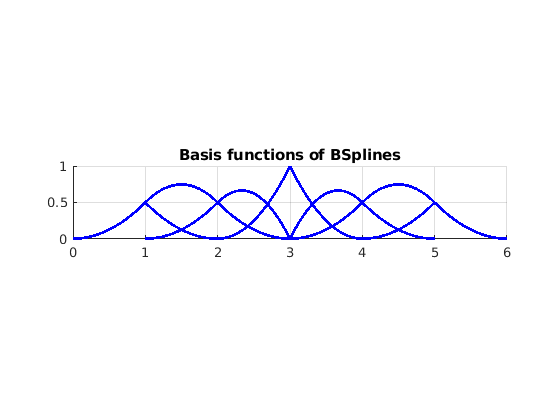



clear all;close all;

%define order
order = 3;
%define knot vector
%knots = [0 0 0 0 0.5 1 1 1 1];
%knots = [-2 -1 0 1 2 3 4 5 6]
%knots = [ 0 0 0 1 1 1];
% knots=[0 0 0 1 2 3 4 4 4];
knots = [0, 1, 2, 3, 3, 4, 5, 6];
%knots = [1 2 3 4 5 6 7 8 9 10 11 12];
%knots = [-10 -8 -6 -4 -2 0 2 4 6];

figure(1);

hold on;

% Plot all basis functions
for span=order-2: length(knots)-order
    u=linspace(knots(span+1),knots(span+2),20);
    f = zeros(order,length(u));

    for i=1:length(u)
        f(:,i)=Basisfuns(u(i), knots, span, order);
    end

%     figure;
%     xlim([0 6])
%     ylim([0 1])

    plot(u,f,'b-',  'linewidth',2);% , 'MarkerFaceColor', 'w', 'MarkerSize',4);
%     xlim([0 6])
%     ylim([-0.1 1.1])

    grid on;
    axis equal
    
end
xlim([0 6])
ylim([0 1])

u=linspace(knots(1),knots(2),20);
y= (u.^2)/2;
plot(u,y,'b-','linewidth',2);
u=linspace(knots(7),knots(8),20);
y=  0.5* ((6-u).^2);
plot(u,y,'b-','linewidth',2);
% set(gca,'FontSize',20)    
% xlabel('x','FontSize',20);
% ylabel('y','FontSize',20);

title("Basis functions of BSplines")